clear all

syms cc
taylor(exp(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}+\frac{{\mathrm{cc}}^{4}}{24}+\frac{{\mathrm{cc}}^{3}}{6}+\frac{{\mathrm{cc}}^{2}}{2}+\mathrm{cc}+1$$

taylor(sin(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}-\frac{{\mathrm{cc}}^{3}}{6}+\mathrm{cc}$$


taylor(exp(cc)) + taylor(sin(cc))+3*taylor(cos(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{60}+\frac{{\mathrm{cc}}^{4}}{6}-{\mathrm{cc}}^{2}+2\,\mathrm{cc}+4$$

input = 2*rand(1000,1)-1;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output);


datasize = length(input);
batchsize = 100;
minis = datasize/batchsize

minis = 10

decay =0.9999

decay = 0.9999

alpha = 0.00001

alpha = 1.0000e-05

alfa = 0.001

alfa = 1.0000e-03

beta= 0

beta = 0

n=4

n = 4

eps = 10^-2

eps = 0.0100


V=zeros(batchsize,1) %momentum

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


B = 0.9

B = 0.9000

V1=0;
V2=0;
V3=0;
V4=0;

X = normalize(rand(n+1,4))/10;
ex= [0:n];

w1= X(:,1);
w2= X(:,2);
w3= X(:,3);



err(1:2)=1;
alfa = 0.0001

alfa = 1.0000e-04

% number of epochs
for i = 2:1000

% Learning rate
alpha=alfa %/(eps+err(i));  
alphas(i)=alpha;    
    
%divide data in batches
indexes= randperm(1000);
batchinput = reshape(input(indexes), [batchsize minis]);    
batchoutput = reshape(output(indexes), [batchsize minis]);

    for j = 1:minis
a1 = batchinput(:,j);
a2 = normalize(a1.^ex*w1);
a3 = normalize(a2.^ex*w2);
a4 = (a3.^ex*w3);

% meansa2(j) = mean(a2);
% meansa3(j) = mean(a3);
% stdsa2(j) = std(a2);
% stdsa3(j) = std(a3);
% a4 = a3.^ex*w3;
% % d4 = a4-batchoutput(:,j);
% d3 = d4 .* [zeros(batchsize,1) ones(batchsize,1) 2*a3 3*a3.^2 4*a3.^3] *w3;

d4 = a4-batchoutput(:,j);
grad3 = gradidi(a3,n);
grad2 = gradidi(a2,n);
grad1 = gradidi(a1,n);
d3 = d4 .* grad3 *w3;
d2 = d3 .* grad2 *w2;
d1 = d2 .* grad1 *w1;

% D = [d2;d1]

V4=B*V4 + (1-B)*d4;
V3=B*V3 + (1-B)*d3;
V2=B*V2 + (1-B)*d2;
V1=B*V1 + (1-B)*d1;

w3 = pinv((a3-beta*alpha*V3).^ex)*(a4-alpha*V4)*decay;
w2 = pinv((a2-beta*alpha*V2).^ex)*(a3-alpha*V3)*decay;
w1 = pinv((a1).^ex)*(a2-alpha*(V2))*decay;

    end

a1=input;
a2 = a1.^ex*w1;
a3 = a2.^ex*w2;
a4 = a3.^ex*w3;

err(i+1) = norm(a4-output)/norm(output);

if (err(i)<0.0001) ||(abs(err(i)-err(i-1))<0.0000001)
    disp("iterations: " + i)
     disp("error: " + err(i))
    break;
end 
end

alpha = 1.0000e-04

iterations: 2


error: 1


disp("error: " + err(i))

error: 1


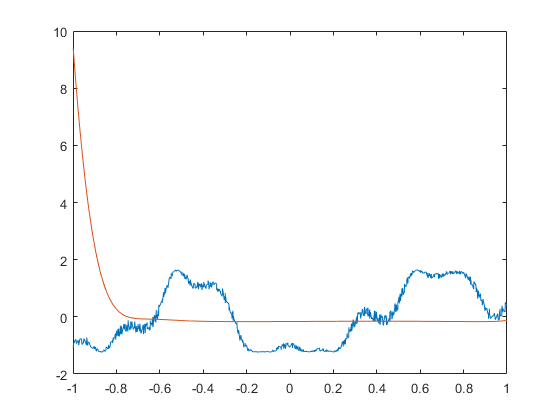


[B1,I] = sort(input);
B2 = output(I);

plot([B1 B1],[B2 a4(I)])

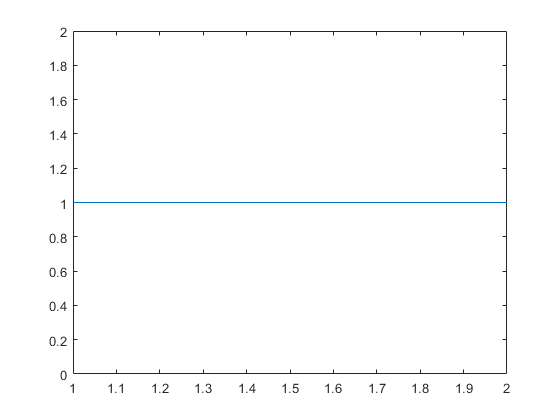


plot(err(1:i))

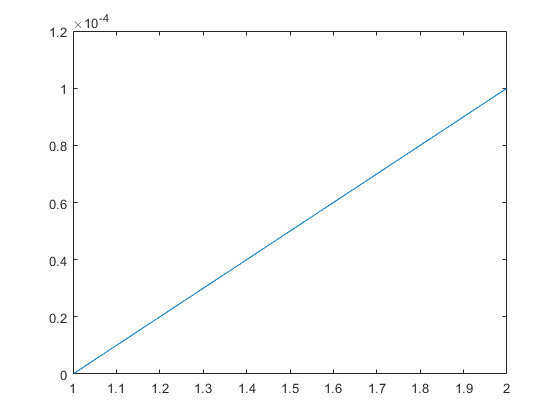

plot(alphas(1:i))


w1

w1 =     0.7337
    2.4271
   -1.4939
   -1.9486
   -0.4276


w2

w2 =    -0.6565
   -0.1251
    0.4231
   -0.3230
    0.1069


w3

w3 =    -0.0974
    0.0797
   -0.0960
   -0.0084
    0.1218



ex=0:3

ex =      0     1     2     3


% zeros(1000,1) ones(1000,1)

w1 =  rand(4,1)

w1 =     0.8976
    0.2886
    0.2690
    0.5942


w2 =  rand(4,1)

w2 =     0.4759
    0.3683
    0.6556
    0.9382



a1 = input(1:200)

a1 =     0.6294
    0.8116
   -0.7460
    0.8268
    0.2647
   -0.8049
   -0.4430
    0.0938
    0.9150
    0.9298



a2 = a1.^ex*w1 

a2 =     1.3341
    1.6267
    0.5854
    1.6559
    1.0039
    0.5298
    0.7710
    0.9276
    1.8422
    1.8761



a3 = a2.^ex*w2

a3 =     4.3616
    6.8482
    1.1044
    7.1433
    2.4556
    0.9946
    1.5794
    2.1303
    9.2443
    9.6702




d3 = a3-output(1:200)

d3 =     2.8602
    5.4292
    1.2268
    5.8859
    3.1579
    1.6584
    0.4048
    3.3581
    9.3091
    9.6646


d2 = d3 .* [zeros(200,1) ones(200,1) 2*a2 3*a2.^2] *w2

d2 =    20.3839
   54.0151
    2.5769
   60.3726
   14.2778
    3.0731
    1.2355
   13.4531
  114.8306
  123.0824


d1 = d3 .* [zeros(200,1) ones(200,1) 2*a1 3*a1.^2] *w1

d1 =     3.8141
   10.3122
    1.0787
   11.4884
    1.7555
    1.6756
    0.1619
    1.1911
   21.1634
   22.5174



w2 = pinv([a2-0.01*d2].^ex)*[a3-0.1*d3]*0.999

w2 =     0.4835
    1.7120
   -0.6987
    2.1711


w1 = pinv(a1.^ex)*[a2-0.01*d2]*0.999

w1 =     0.8734
    0.3920
   -0.2350
   -0.1840



% ---------
a2 = a1.^ex*w1;

a3 = a2.^ex*w2;

C = 0.5*(a3-output(1:200)).^2;
norm(C)/norm(output(1:200))

ans = 4.6540

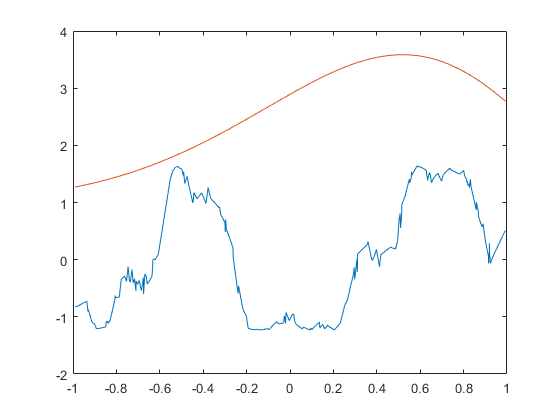




[B1,I] = sort(input(1:200));
B2 = output(I);

plot([B1 B1],[B2 a3(I)])


w1

w1 =     0.8734
    0.3920
   -0.2350
   -0.1840


w2

w2 =     0.4835
    1.7120
   -0.6987
    2.1711


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10


newin = input

newin =     0.6294
    0.8116
   -0.7460
    0.8268
    0.2647
   -0.8049
   -0.4430
    0.0938
    0.9150
    0.9298


newout = output

newout =     1.5014
    1.4190
   -0.1225
    1.2574
   -0.7023
   -0.6638
    1.1746
   -1.2278
   -0.0648
    0.0056



[B1,I] = sort(newin);

newin(I(200:700))=[]

newin =     0.6294
    0.8116
   -0.7460
    0.8268
   -0.8049
    0.9150
    0.9298
   -0.6848
    0.9412
    0.9143


newout(I(200:700))=[]

newout =     1.5014
    1.4190
   -0.1225
    1.2574
   -0.6638
   -0.0648
    0.0056
   -0.5433
    0.1066
    0.0883



newin.^ex

ans =     1.0000    0.6294    0.3962    0.2494    0.1570    0.0988    0.0622    0.0391    0.0246    0.0155    0.0098
    1.0000    0.8116    0.6587    0.5346    0.4338    0.3521    0.2858    0.2319    0.1882    0.1528    0.1240
    1.0000   -0.7460    0.5566   -0.4152    0.3098   -0.2311    0.1724   -0.1286    0.0959   -0.0716    0.0534
    1.0000    0.8268    0.6835    0.5651    0.4672    0.3863    0.3193    0.2640    0.2183    0.1805    0.1492
    1.0000   -0.8049    0.6479   -0.5215    0.4198   -0.3379    0.2720   -0.2189    0.1762   -0.1418    0.1142
    1.0000    0.9150    0.8373    0.7661    0.7010    0.6414    0.5869    0.5370    0.4914    0.4496    0.4114
    1.0000    0.9298    0.8645    0.8038    0.7473    0.6949    0.6461    0.6007    0.5585    0.5193    0.4828
    1.0000   -0.6848    0.4689   -0.3211    0.2199   -0.1506    0.1031   -0.0706    0.0483   -0.0331    0.0227
    1.0000    0.9412    0.8858    0.8337    0.7847    0.7385    0.6951    0.6542    0.6157    0.5795    0.

www = pinv(newin.^ex)*(newout);

I(200:700)=[]

I =    609
   452
   123
   448
   872
   772
    99
   746
   174
   333


B2 = newout(I);

Index exceeds the number of array elements (499).


recon = input.^ex*www


plot([B1 B1],[B2 recon(I)])

rataa = norm(recon-newout)/norm(newout)
